# Hands-On AI for Smart Appliances: From Sensor Data to Embedded Code

## **1. Introduction **

**Problem Overview**

Localized faults in a rolling element bearing may occur in the outer race, the inner race, the cage, or a rolling element. High frequency resonances between the bearing and the response transducer are excited when the rolling elements strike a local fault on the outer or inner race, or a fault on a rolling element strikes the outer or inner race [1]. The following picture shows a rolling element striking a local fault at the inner race. The problem is how to detect and identify the various types of faults.

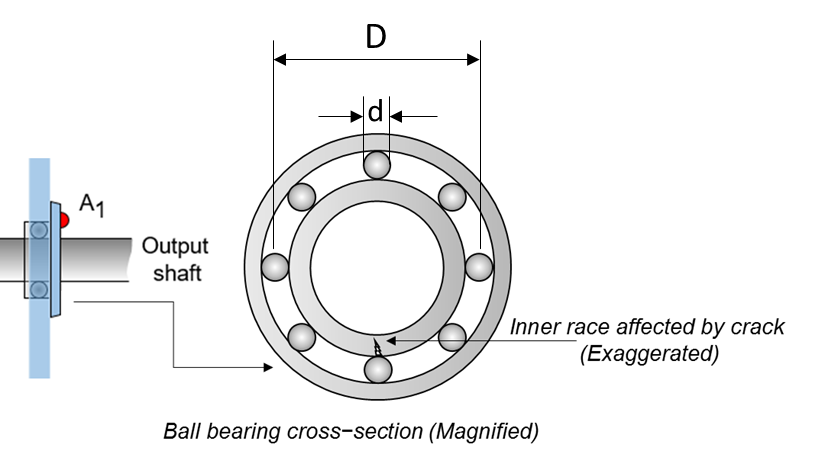

## Machinery Failure Prevention Technology (MFPT) Challenge Data

[GitHub - mathworks/RollingElementBearingFaultDiagnosis-Data: Data set for Rolling Element Bearing Fault Diagnosis example in Predictive Maintenance Toolbox](https://github.com/mathworks/RollingElementBearingFaultDiagnosis-Data)

MFPT Challenge data [4] contains 23 data sets collected from machines under various fault conditions. The first 20 data sets are collected from a bearing test rig, with 3 under good conditions, 3 with outer race faults under constant load, 7 with outer race faults under various loads, and 7 with inner race faults under various loads. The remaining 3 data sets are from real-world machines: an oil pump bearing, an intermediate speed bearing, and a planet bearing. The fault locations are unknown. In this example, only the data collected from the test rig with known conditions are used.

Each data set contains an acceleration signal "gs", sampling rate "sr", shaft speed "rate", load weight "load", and four critical frequencies representing different fault locations: ballpass frequency outer race (BPFO), ballpass frequency inner race (BPFI), fundamental train frequency (FTF), and ball spin frequency (BSF). Here are the formulae for those critical frequencies [1]. 

- Ballpass frequency, outer race (BPFO)


$$BPFO = \frac{nf_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ballpass frequency, inner race (BPFI)


$$BPFI = \frac{nf_r}{2}\left(1+\frac{d}{D}\cos \phi\right)$$


- Fundamental train frequency (FTF), also known as cage speed


$$FTF = \frac{f_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ball (roller) spin frequency


$$BSF = \frac{Df_r}{2d}\left[1-\left(\frac{d}{D}\cos \phi\right)^2\right]$$


As shown in the figure, $d$ is the ball diameter, $D$ is the pitch diameter. The variable $f_r$ is the shaft speed, $n$ is the number of rolling elements, $\phi$ is the bearing contact angle [1].

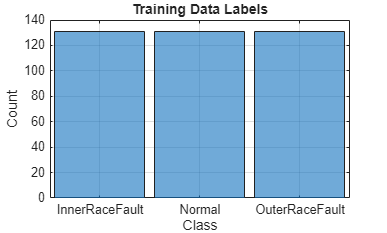

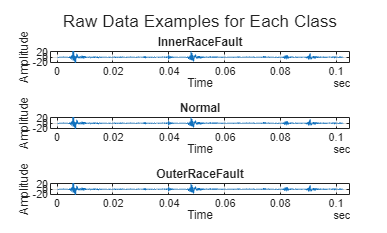

load("valTable.mat")
load("trainTable.mat")
load("testTable.mat")
plotRawData(trainTable)

Using Diagnostic Feature Designer (DFD) App, extract and select feature, generate function to extract those features.

diagnosticFeatureDesigner

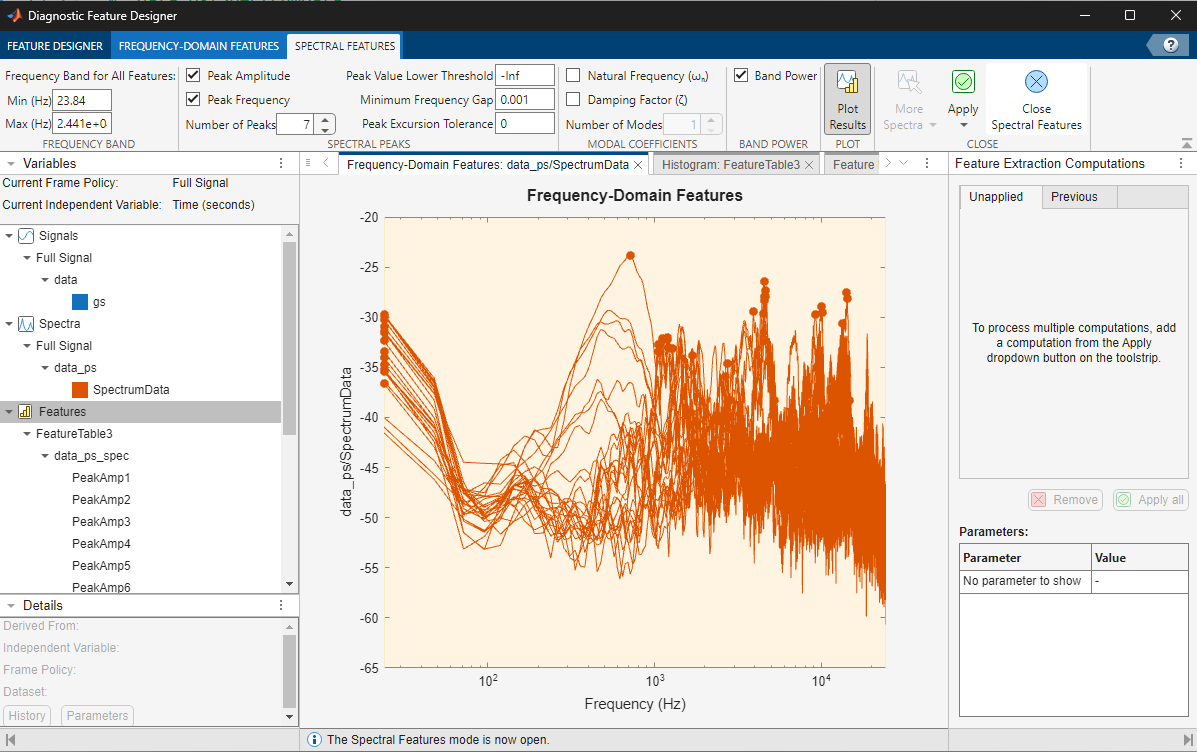

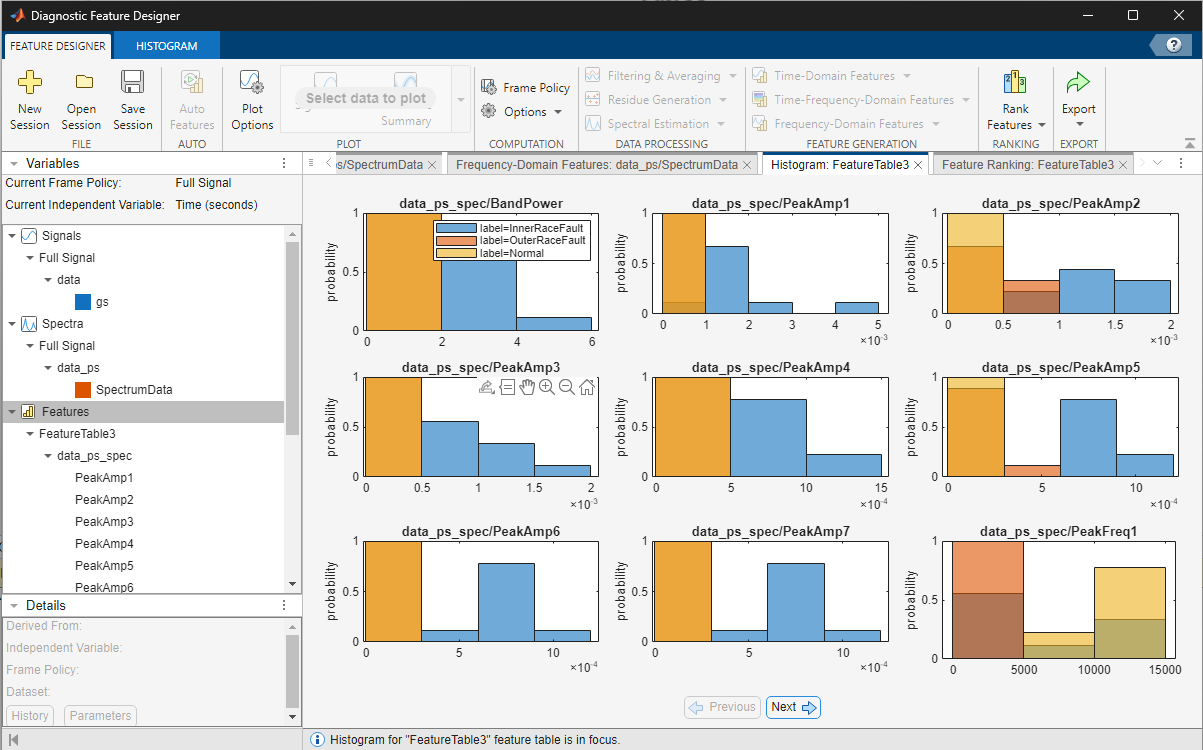

Use the generated function to extract features for the training, validation, and testing data.

feaTest = diagnosticFeatures(testTable);
feaTrain = diagnosticFeatures(trainTable)

feaTrain = 393×7 table
        label         data_ps_spec/PeakAmp3    data_ps_spec/PeakAmp4    data_ps_spec/PeakAmp5    data_ps_spec/PeakAmp6    data_ps_spec/PeakAmp7    data_ps_spec/BandPower
    ______________    _____________________    _____________________    _____________________    _____________________    _____________________    ______________________

    InnerRaceFault         0.00083332               0.00081439               0.00080294               0.00072909               0.00071383                    4.27        
    InnerRaceFault          0.0012205                0.0011876                0.0010295               0.00098555               0.00095191                  3.6811        
    InnerRaceFault         0.00098629               0.0008

save features.mat feaTrain feaTest 

Refer to [Rolling Element Bearing Fault Diagnosis - MATLAB & Simulink](https://www.mathworks.com/help/predmaint/ug/Rolling-Element-Bearing-Fault-Diagnosis.html) for more techniques for extracting features for bearing fault diagnosis.

**Helper Function**

function plotRawData(originalData)
labels = string(originalData.label); % Directly access the Label column
unqiqueLabels = unique(labels);
figure;
histogram(categorical(labels, unique(labels)), 'DisplayOrder', 'ascend');
xlabel('Class',Interpreter='none');
ylabel('Count',Interpreter='none');
title('Training Data Labels',Interpreter='none');
grid on;

figure('Name','Raw Data ');tiledlayout(3,1)
numClasses = numel(unqiqueLabels);
for c = 1:numClasses
    nexttile
    TT = originalData.data{1};
    plot(TT.Time,TT.gs);
    xlabel('Time');
    ylabel('Amplitude');
    title(unqiqueLabels(c), 'Interpreter','none');
    grid on;
end
sgtitle('Raw Data Examples for Each Class');
end
